%% This file makes use of the following functions from Matlab Functions Library
% imagedata
% ImagingResonanceFit

filenames_s1 = {};
imgfreqs_s1 = [];
filenames_s2 = {};
imgfreqs_s2 = [];

cropset = {'rect',109,336,60,60};
bgset = {'avg',10};

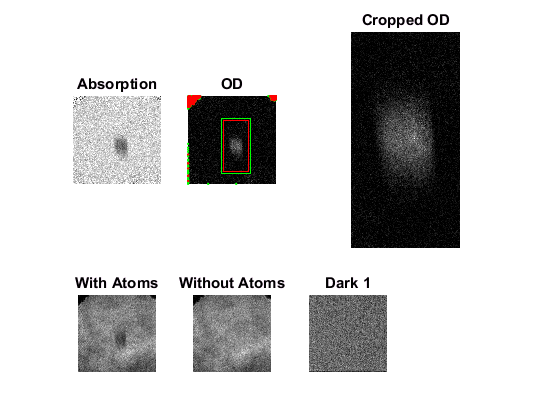

atoms_s1 = zeros(size(filenames_s1));
% Sample Crop
imagedata(filenames_s1{1},'crop',cropset,'bg',bgset,'plot',{1});

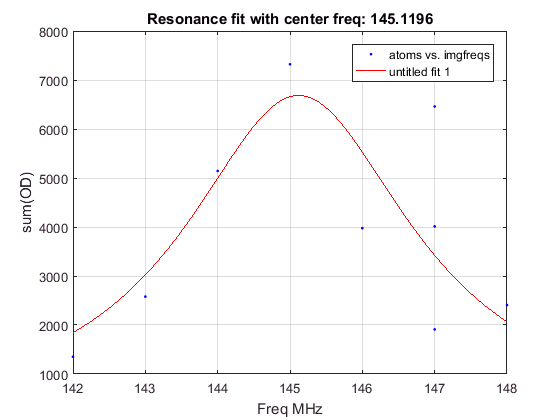


for i = 1:length(filenames_s1)
    temp = imagedata(filenames_s1{i},'crop',cropset,'bg',bgset,'plot',{0}); %,'Nsat',630
    atoms_s1(i) = sum(sum(temp.od2));
end
fitres_s1 = ImagingResonanceFit(imgfreqs_s1,atoms_s1);


% save([datestr(datetime,'yyyy-mm-dd'),'-State1-ImgRes-Data.mat'],'filenames_s1','imgfreqs_s1');

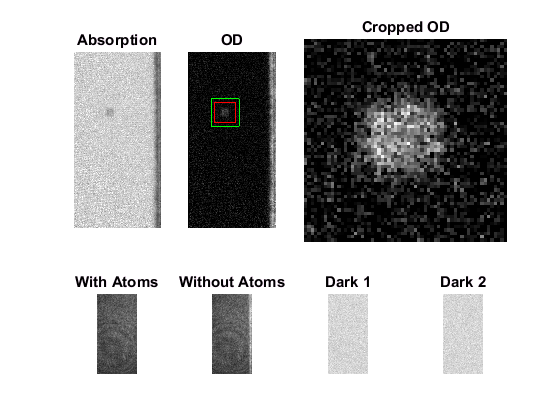

atoms_s2 = zeros(size(filenames_s2));
% Sample Crop
imagedata(filenames_s2{1},'crop',cropset,'bg',bgset,'plot',{1});

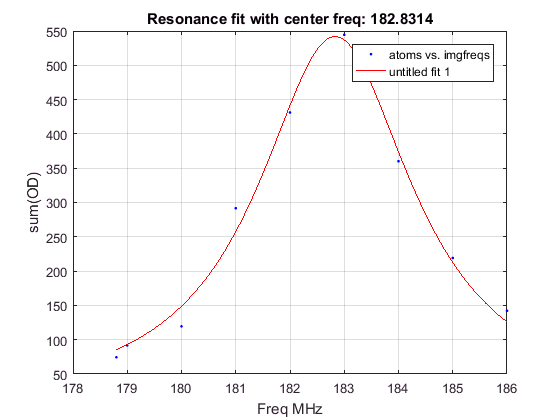


for i = 1:length(filenames_s2)
    temp = imagedata(filenames_s2{i},'crop',cropset,'bg',bgset,'plot',{0}); %,'Nsat',630);
    atoms_s2(i) = sum(sum(temp.od2));
end
fitres_s2 = ImagingResonanceFit(imgfreqs_s2,atoms_s2);


% save([datestr(datetime,'yyyy-mm-dd'),'-State2-ImgRes-Data.mat'],'filenames_s2','imgfreqs_s2');